## Tutorial: how to extract a STL file containing multiple objects into individual STL files

Suppose you are simulating some packing of particles. This could be used for fluid flow and heat transfer analysis in porous media, magnetic simulations of grains, some novel design and manufacturing technique etc. 

A possible workflow is to construct a *geometric* model in a 3D software; we'll cite [Blender](https://www.blender.org/) because this is what is used in the test files in this project. This very tutorial contains such a file, `all_particles`, which consists of circa 200 hexagonal prisms of different sizes and shapes.

**Note: currently, **`STLExtractor`** only supports extraction of hexagonal prisms. This could be extended in future releases.**

The main model for this package is called `STLExtractor`:

help STLExtractor

 STLExtractor Extract individual objects from an STL FILE
    Objects of this class can process an STL file and retrieve individual hexagonal
       prims. The goal is to extract individual "particles" from a "packing".

    Documentation for STLExtractor



To actually instantiate one, you need the name of the STL file you want to process and a directory where you want to save the individual files:

tutorialsDir = fileparts(which('Tutorial1_Extract'));
exampleFile = fullfile(tutorialsDir,"all_particles.stl");
outputDir = fullfile(tutorialsDir,"tmp");
% create folder if not existent
if ~isfolder(outputDir)
    mkdir(outputDir);
end

extractor = STLExtractor(exampleFile,outputDir);

Then, you call the `process` method:

l = extractor.process;

The returned object is:

disp(l);

  ExtractedPacking with properties:

                                        items: [1×184 HexagonalPrism]
                                         xmin: -2.2725
                                         xmax: 2.2727
                                         ymin: -2.2725
                                         ymax: 2.2722
                                         zmin: -2.2727
                                         zmax: 2.5817
                                           Lx: 4.5452
                                           Ly: 4.5447
                                           Lz: 4.8545
                                       volume: 100.2780
                    volumetricFillingFraction: 0.7076
                            averageAlignmentX: 0.0033
                  standardDeviationAlignmentX: 0.5247
              volumeWeightedAverageAlignmentX: -0.0052
    volumeWeightedStandardDeviationAlignmentX: 0.2257
 

Where you can see it recognized almost 200 prisms.

You can also plot:

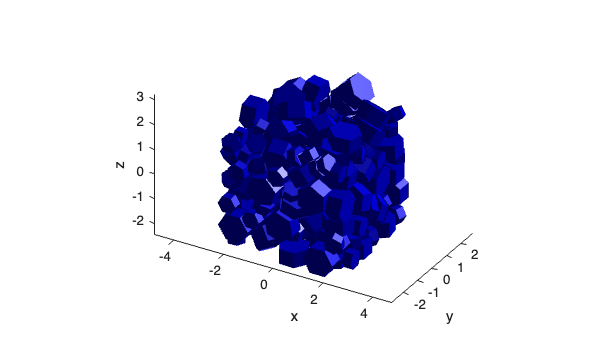

ans =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [9.5779 7.3290 16.0000 9.0000]
       Units: 'centimeters'

  Show all properties


l.plot